# **Interpolate Homogeneous Transformation Matrix**

- **Linear Path**

- **Screw Path**

clc;clear;
[filepath,~,~] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(filepath);
addpath(fullfile(filepath,'myfunc'),'-begin')

**2 Frames**

% T0 = randSE3(pi,10);
% T1 = randSE3(pi,10);
load('testdata.mat')
n = 100;

## **Linear Motion, Constant Step**

**Interpolation**

s_path = linspace(0,1,n); % steps
T_path = interpSE3(T0,T1,s_path,'linear');

**Plot**

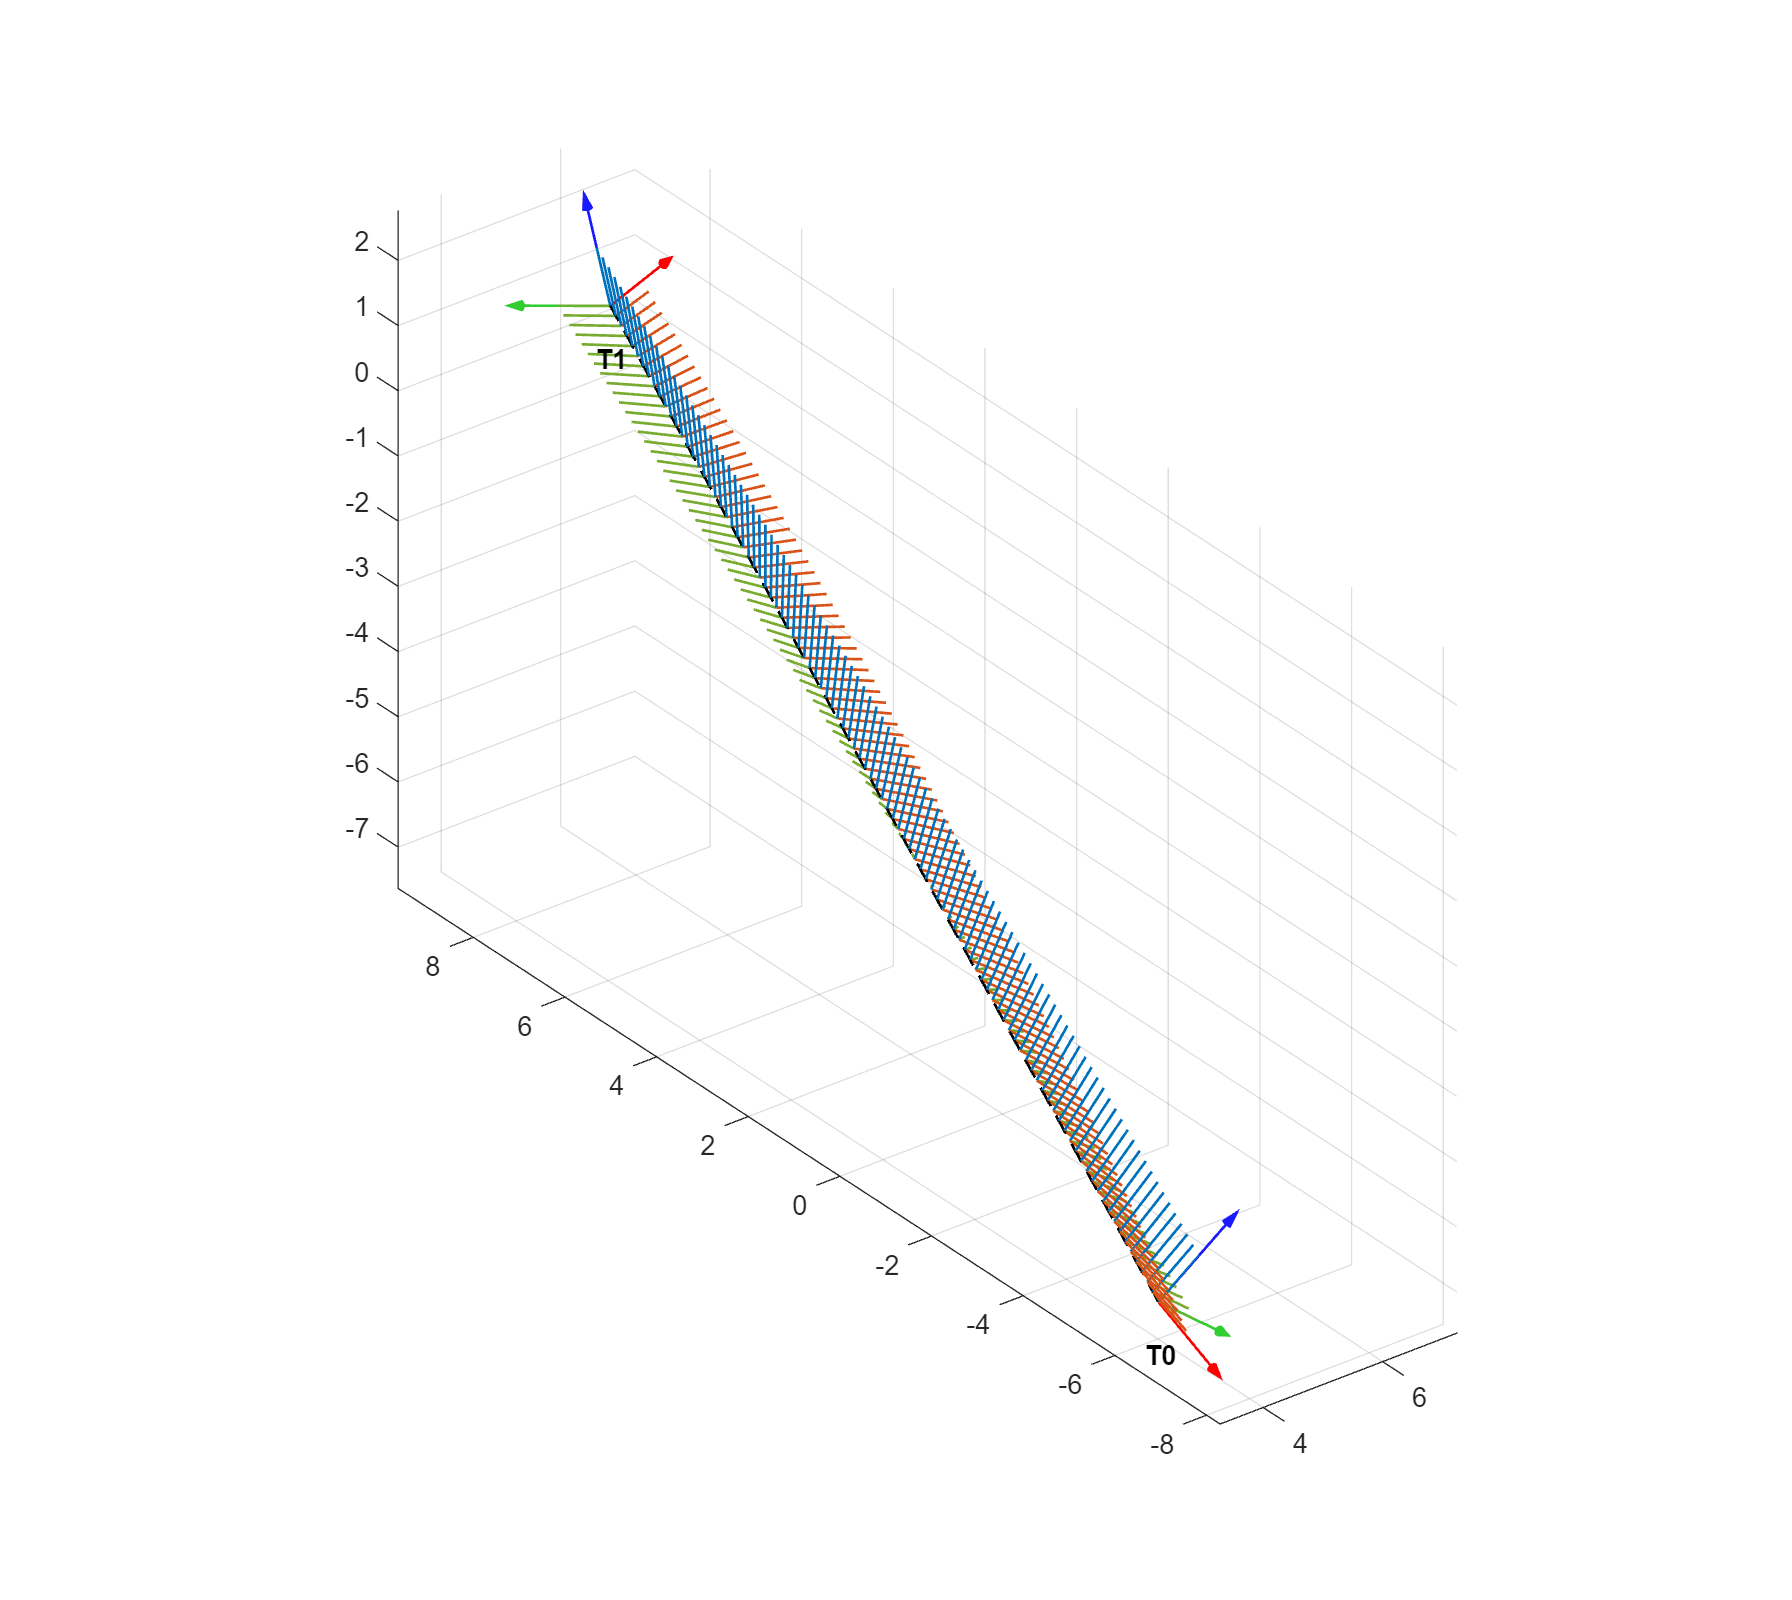

f = figure;
plotpath(T0,T1,T_path);
set(f,'Units','normalized','Position',[0,0,0.7,1])

## **Linear Motion, Variant Step**

**Interpolation**

[s_path,v] = vcurve(n,[0.6,0.2],'sine');
T_path = interpSE3(T0,T1,s_path,'linear');

**Plot Velocity and Distant Curve**

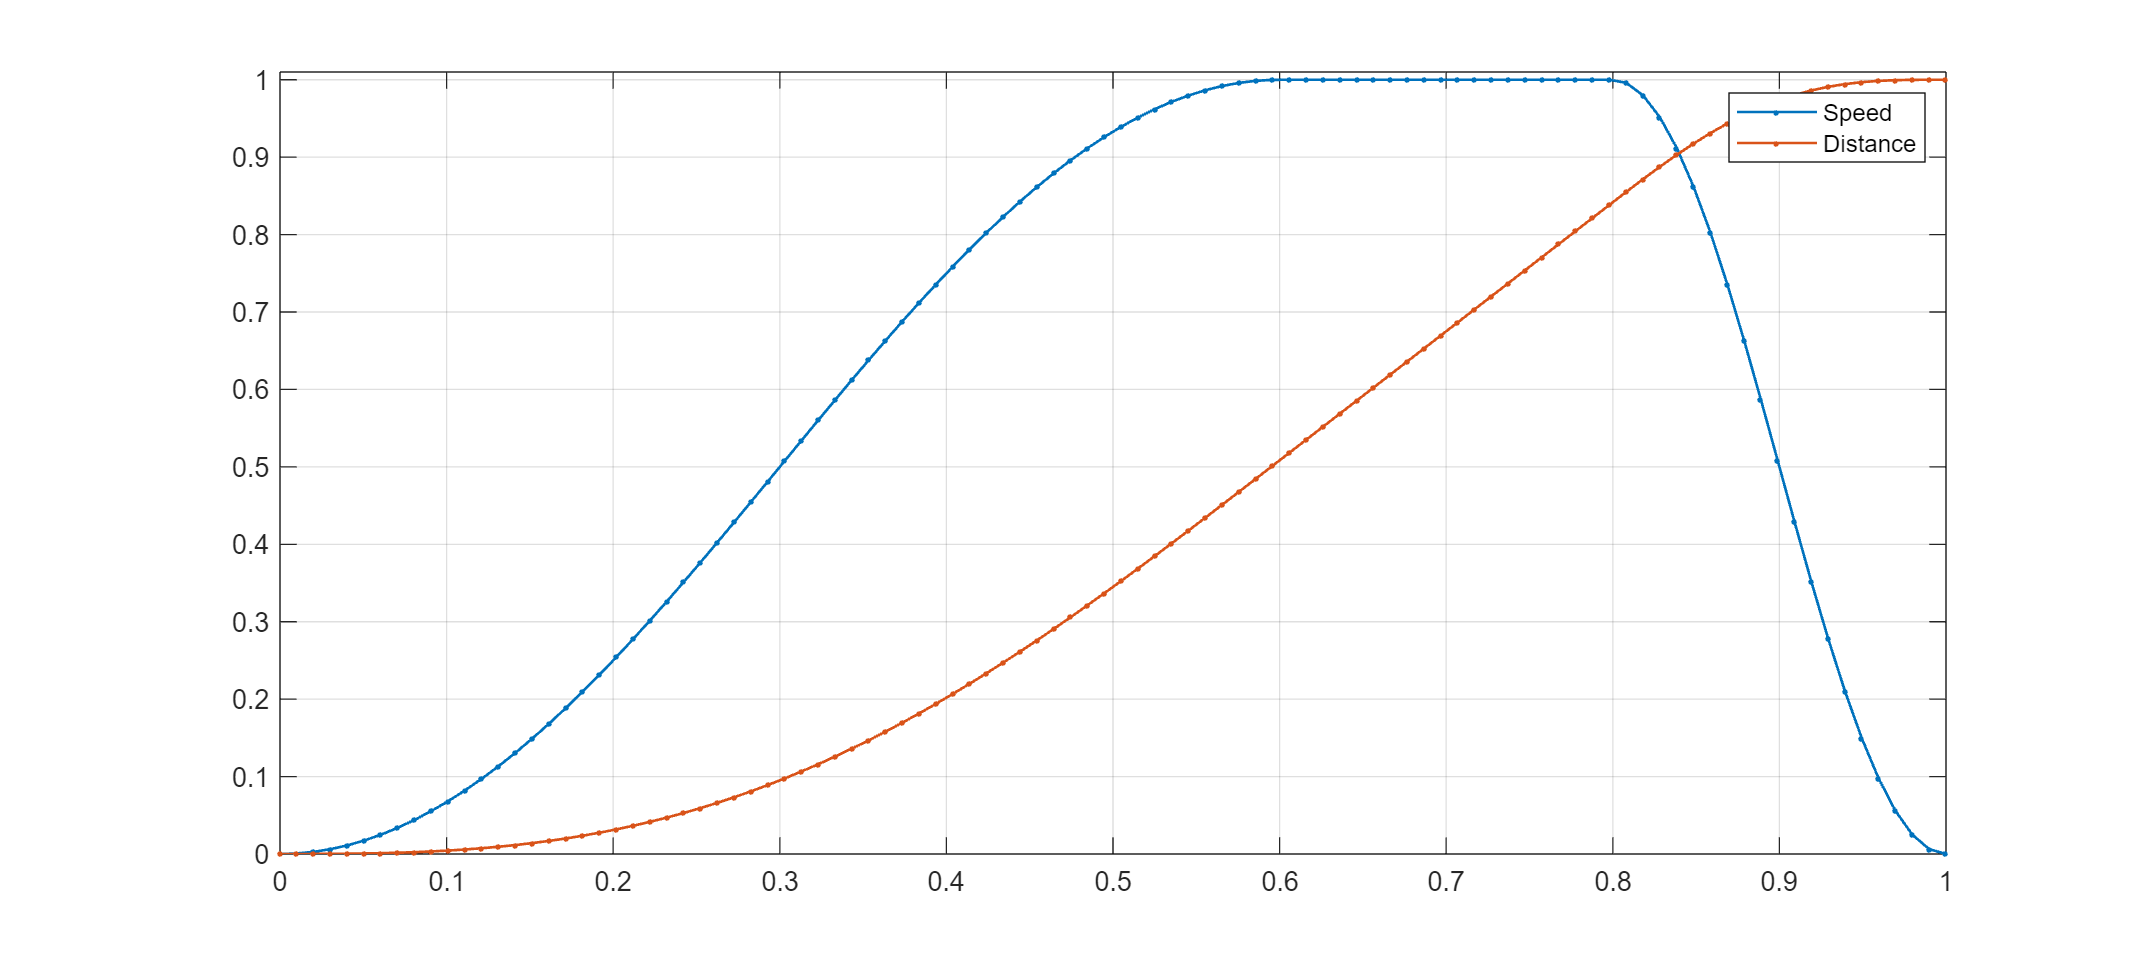

f = figure;
plot(linspace(0,1,n),v,'.-','LineWidth',1); hold on
plot(linspace(0,1,n),s_path,'.-','LineWidth',1); hold on
grid on; xlim([0,1]); ylim([0,1.01]);
legend('Speed','Distance')
set(f,'Units','normalized','Position',[0,0,0.7,0.5])

**Plot**

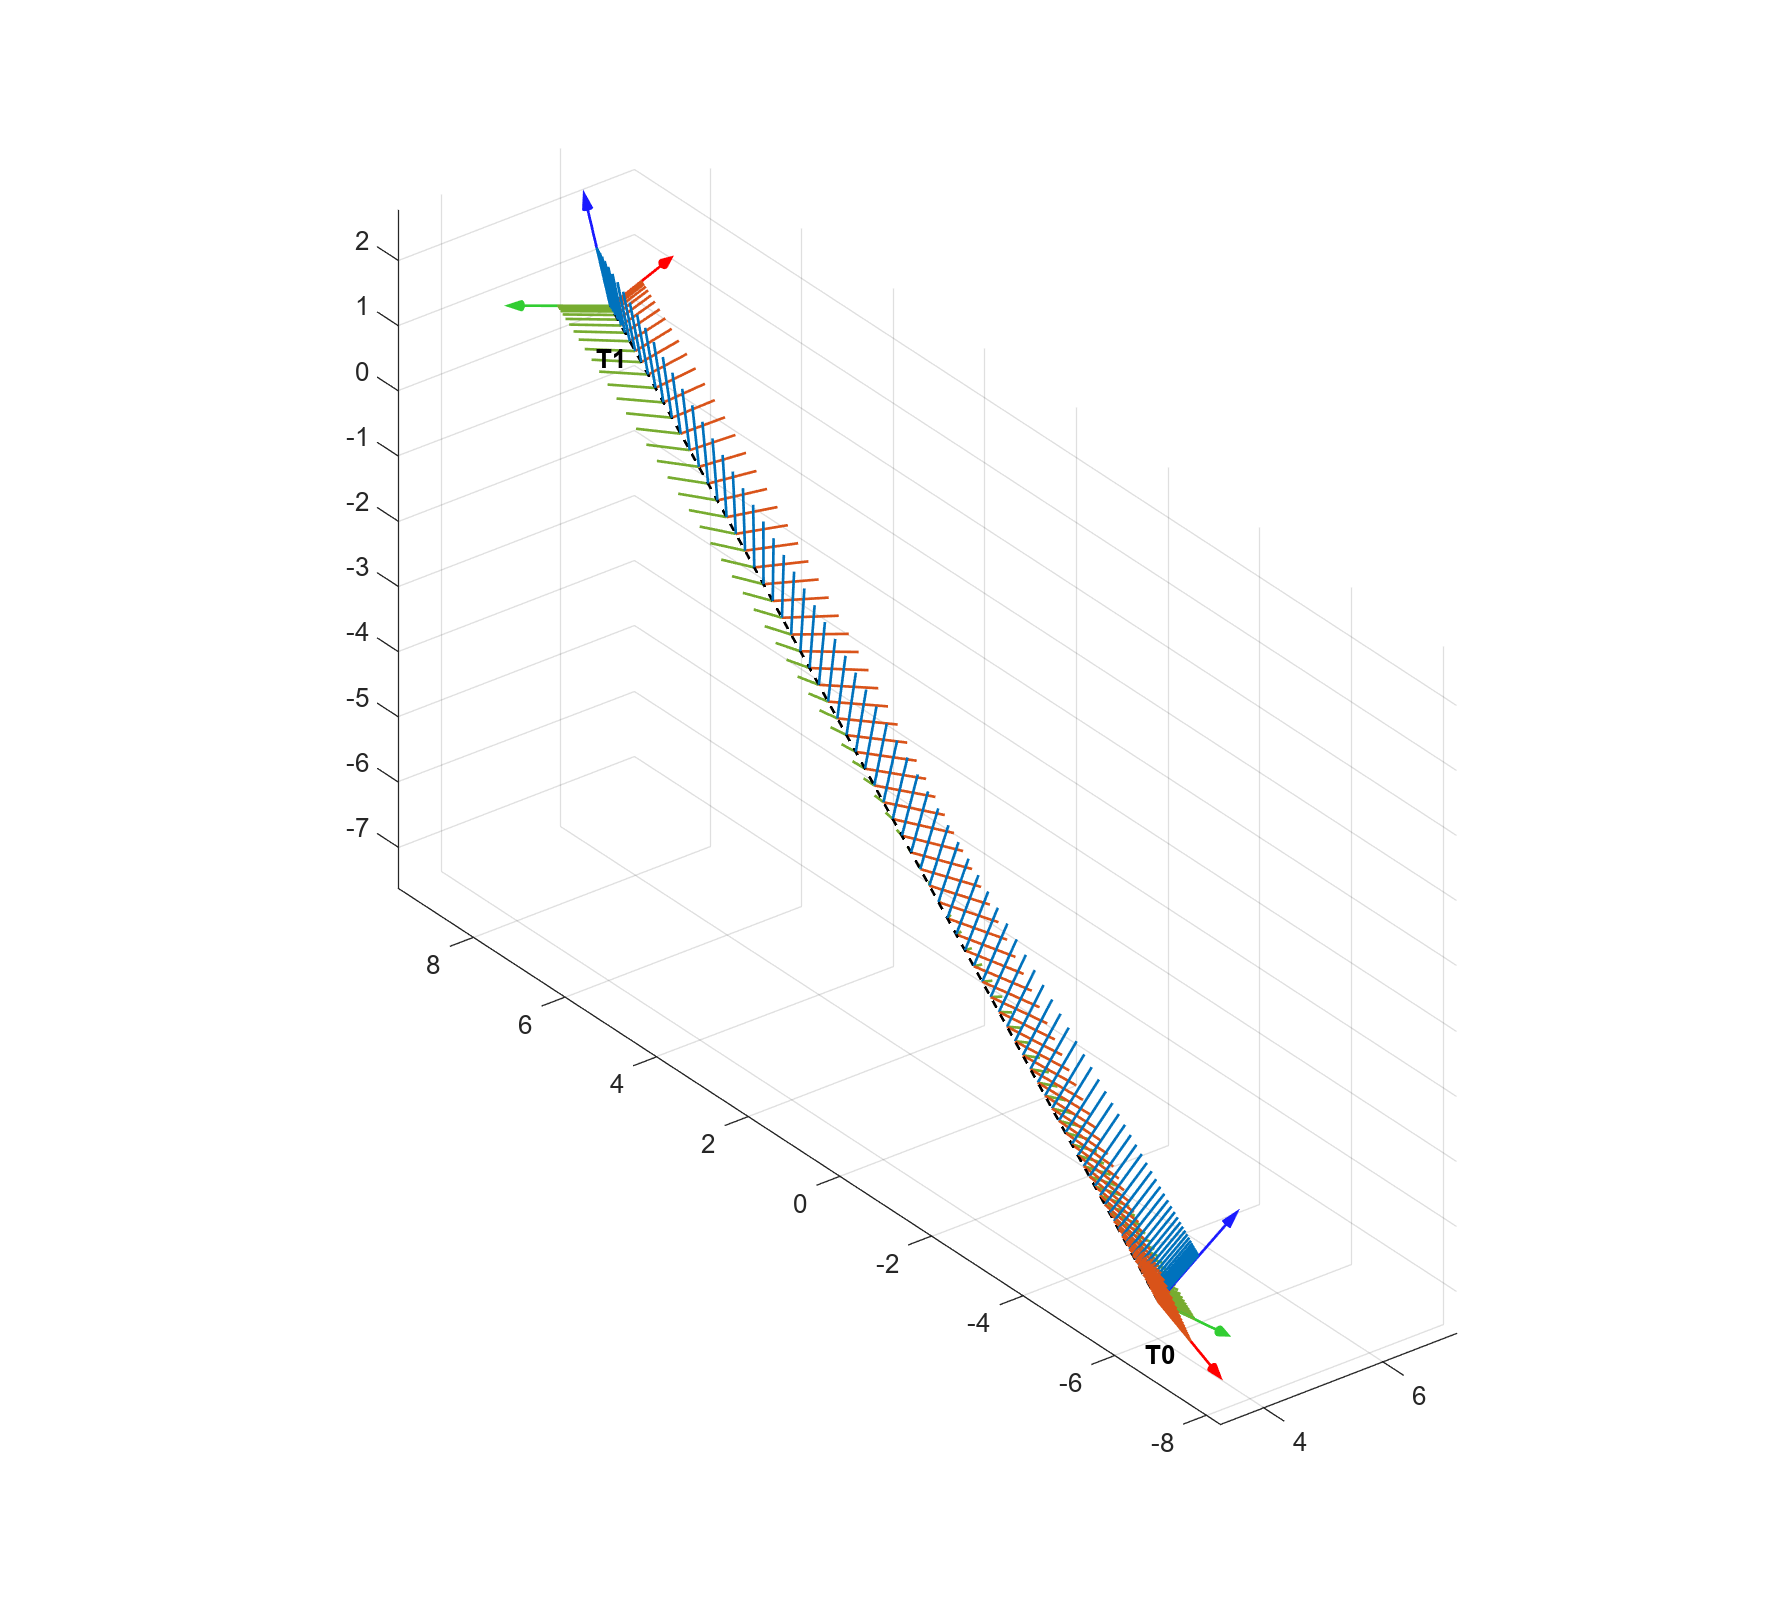

f = figure;
plotpath(T0,T1,T_path);
set(f,'Units','normalized','Position',[0,0,0.7,1])

## Screw Motion, Constant Step

**Interpolation**

s_path = linspace(0,1,n); % steps
T_path = interpSE3(T0,T1,s_path,'screw');

**Plot**

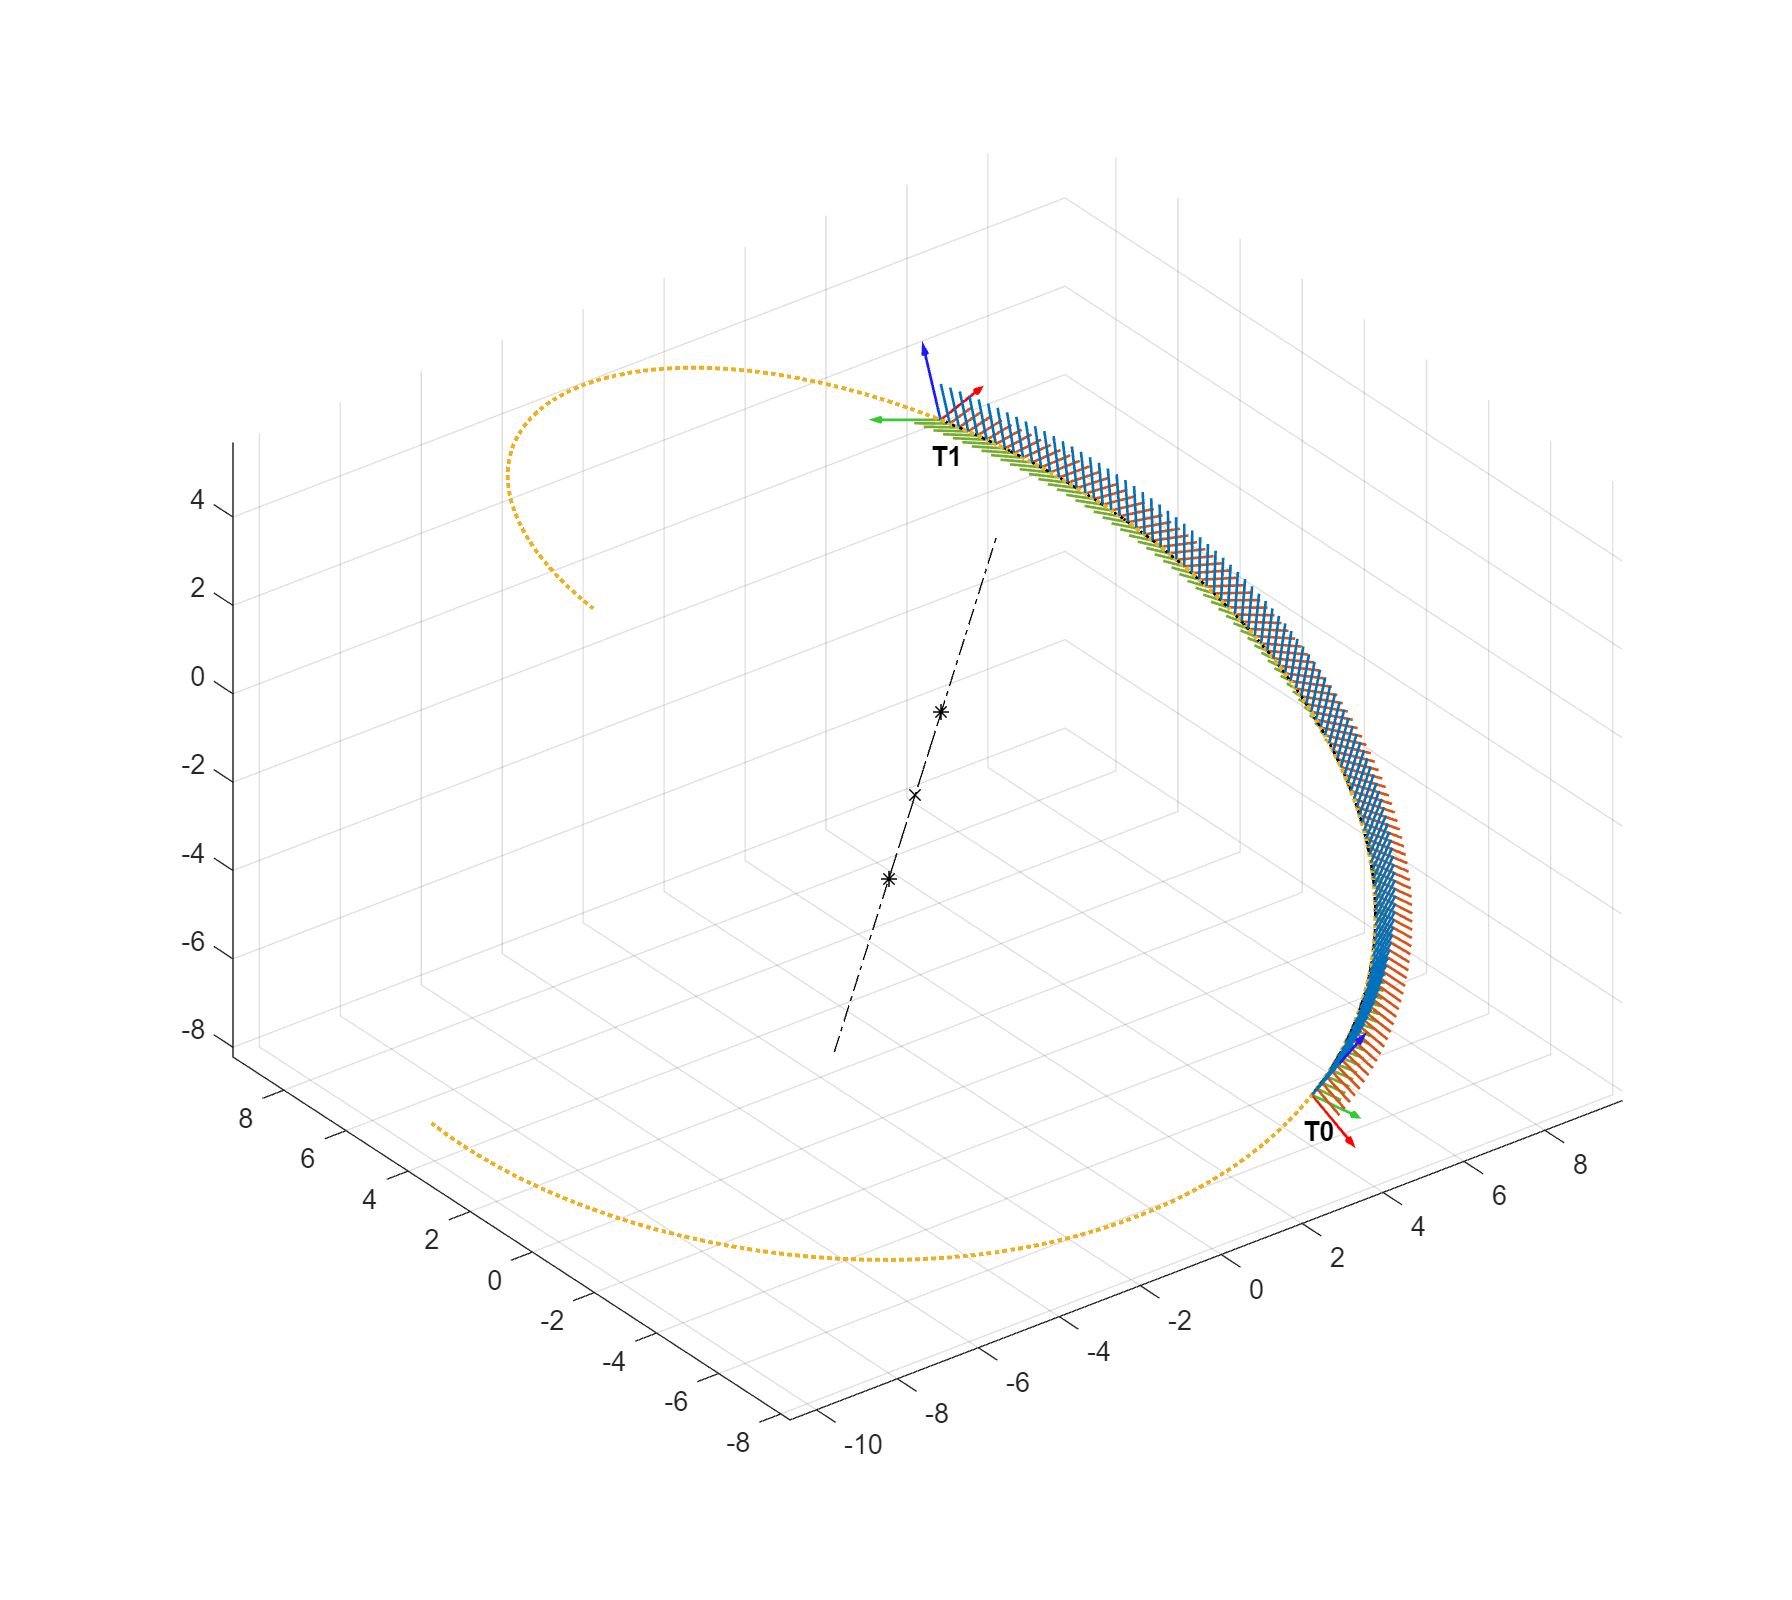

plotdata = GetScrewPlotData(T0,T1,[9999,1/180*pi],1); % for plot axis and 360 full motion 
Center = plotdata.Center;
ProjPt = plotdata.ProjPt;
Axis = plotdata.Axis;
FPath = plotdata.FPath;

f = figure;
plotpath(T0,T1,T_path);
p(1) = plot3(Center(1),Center(2),Center(3),'xk'); hold on
p(2) = plot3(ProjPt(1,:),ProjPt(2,:),ProjPt(3,:),'*-.k'); hold on
plot3(Axis(1,:),Axis(2,:),Axis(3,:),'-.k'); hold on
p(3) = plot3(FPath(1,:),FPath(2,:),FPath(3,:),':','LineWidth',1.5,'Color',[0.9290 0.6940 0.1250]);
set(f,'Units','normalized','Position',[0,0,0.7,1])

function plotpath(T0,T1,T_path)
dist = norm(T0(1:3,4)-T1(1:3,4));
scale = dist/10;
T(:,:,1) = T0; T(:,:,2) = T1;
P_path = reshape(T_path(1:3,4,:),3,[]);
plot3(P_path(1,:),P_path(2,:),P_path(3,:),'--k','LineWidth',1); hold on
for i = 1:2
    PlotFrame(T(:,:,i),'scale',scale,'linewidth',1,...
        'style','-','colorind',1,'arrowsize',1/6,'text','off');hold on
    text(T(1,4,i)-1,T(2,4,i)-1,T(3,4,i),['T',num2str(i-1)],"FontWeight","bold")
end
for i = 1:size(T_path,3)
    PlotFrame(T_path(:,:,i),'scale',scale/2,'linewidth',1,...
        'style','-','colorind',2,'text','off');hold on    
end
grid on; axis equal; 
end